# **Sygnals and systems - Dr. Akhavan**

## **CA4 - Matin Bazrafshan**

# Part 1: 

## 1.1 creating mapset

mapset = create_mapset()

mapset = 2×32 cell array
    {'a'    }    {'b'    }    {'c'    }    {'d'    }    {'e'    }    {'f'    }    {'g'    }    {'h'    }    {'i'    }    {'j'    }    {'k'    }    {'l'    }    {'m'    }    {'n'    }    {'o'    }    {'p'    }    {'q'    }    {'r'    }    {'s'    }    {'t'    }    {'u'    }    {'v'    }    {'w'    }    {'x'    }    {'y'    }    {'z'    }    {' '    }    {'.'    }    {','    }    {'!'    }    {'"'    }    {';'    }
    {'00000'}    {'00001'}    {'00010'}    {'00011'}    {'00100'}    {'00101'}    {'00110'}    {'00111'}    {'01000'}    {'01001'}    {'01010'}    {'01011'}    {'01100'}    {'01101'}    {'01110'}    {'01111'}    {'10000'}    {'10001'}    {'10010'}    {'10011'}    {'10100'}    {'10101'}    {'10110'}    {'10111'}    {'11000'}    {'11001'}    {'11010'}    {'11011'}    {'11100'}    {'11101'}    {'11110'}    {'11111'}


## 1.2 encoding message:

message = 'signal';
encode_string(message, mapset)

ans = '100100100000110011010000001011'

## 1.3, 1.4 coding into a signal and decoding

note: if length of bit string is not dividable by bitrate, I add as many as need semicolon ';' to fix the issue. 

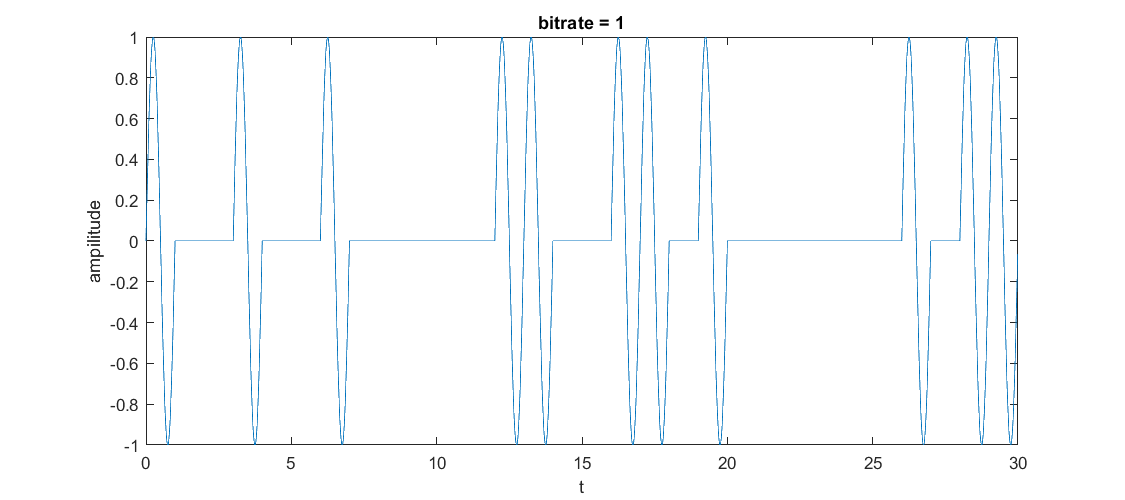

decoded message: signal

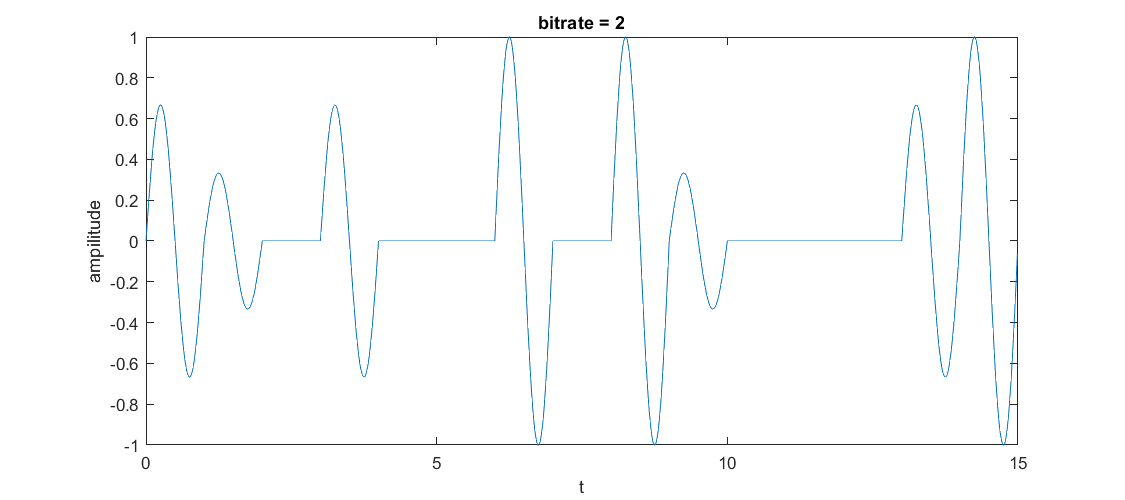

decoded message: signal

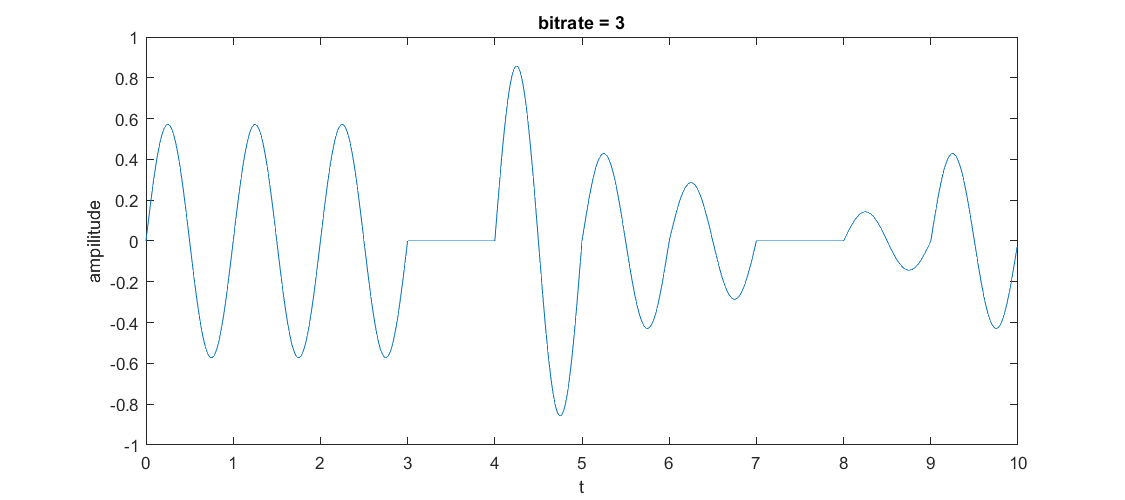

decoded message: signal

bit_rates = [1,2,3];
ts = 0.01;
for i = 1:length(bit_rates)
    y = coding_amp(message, bit_rates(i), mapset);
    t = 0:ts:length(y)/100 - ts;
    figure('Position', [0 0 900 400]);
    plot(t, y);
    xlabel('t');
    ylabel('ampilitude');
    title("bitrate = " + num2str(bit_rates(i)));
    fprintf("decoded message: %s", decoding_amp(y, bit_rates(i), mapset));
end

## 1.5 Creating gaussian-distributed noise

guassian_random = randn(1,3000);

We plot density histogram of random numbers along with normal distribution(with mean = 0 and std = 1) in a same plot, so we can compare them.

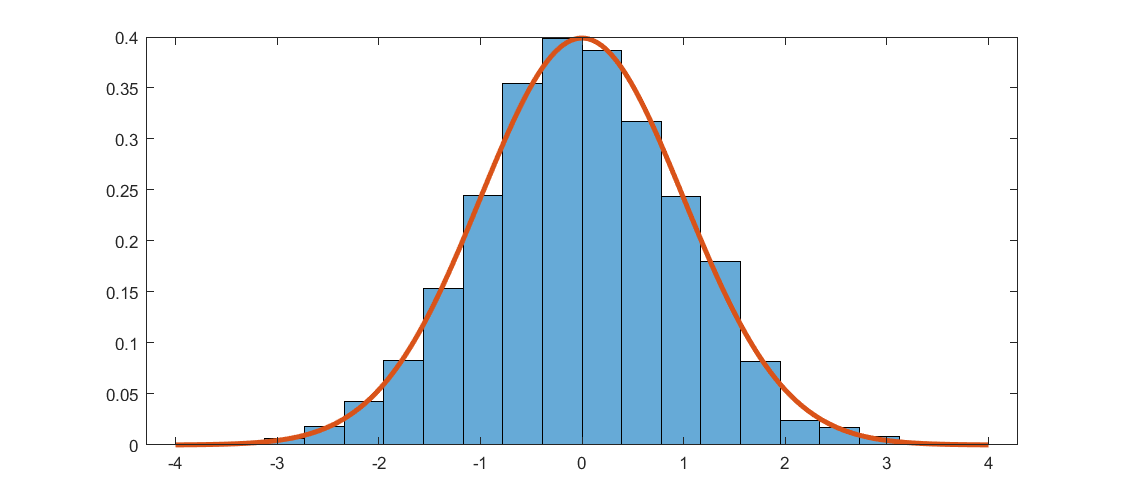

histogram(guassian_random, 20, "Normalization", "pdf");
hold on;
plot(-4:0.01:4, normpdf(-4:0.01:4, 0, 1), "LineWidth", 3);
hold off;

As we expected, the mean is almost 0, and the standard deriviation is almost 1.

mean(guassian_random)

ans = -0.0093

var(guassian_random)

ans = 0.9943

## 1.6 Adding noise with std = 0.0001

std = 0.0001;

bit_rates = [1,2,3];
fprintf("result of decoding by setting std = %.4f\n", std)

result of decoding by setting std = 0.0001


for i = 1:length(bit_rates)
    y = coding_amp(message, bit_rates(i), mapset);
    y = y + std * randn(size(y));
    fprintf("bit rate: %d - result: %s\n", bit_rates(i), decoding_amp(y,  bit_rates(i), mapset));
end

bit rate: 1 - result: signal
bit rate: 2 - result: signal
bit rate: 3 - result: signal


As we can see, the message decoded correctly. because a noise with std = 0.0001 does not affect considerably.

## 1.7, 1.8 Increasing noise effect

As we can see in bitrate = 1, we have right decoded message up to std = 1.7, this value is 0.7 for bitrat = 2 and 0.3 for bitrate = 3.

**so: bitrate **$\to$** maxumim std with correct value**

- 1 $\to$ 1.7

- 2 $\to$ 0.7

- 3 $\to$ 0.3

As we can see the bitrate 1 is more resistant againt noise, because abseloute difference of correlation thresholds is bigger number so adding noise has less effect on changing bits. 

for i = 1:length(bit_rates)
    fprintf("bitrate: %d", bit_rates(i));
    for variance = 0.1:0.1:2
        y = coding_amp(message, bit_rates(i), mapset);
        y = y + variance * randn(size(y));
        decoded = decoding_amp(y, bit_rates(i), mapset);
        fprintf("variance: %.1f, decoded: %s\n", variance, decoded)
    end
end

bitrate: 1

variance: 0.1, decoded: signal
variance: 0.2, decoded: signal
variance: 0.3, decoded: signal
variance: 0.4, decoded: signal
variance: 0.5, decoded: signal
variance: 0.6, decoded: signal
variance: 0.7, decoded: signal
variance: 0.8, decoded: signal
variance: 0.9, decoded: signal
variance: 1.0, decoded: signal
variance: 1.1, decoded: signal
variance: 1.2, decoded: signal
variance: 1.3, decoded: signal
variance: 1.4, decoded: signal
variance: 1.5, decoded: signal
variance: 1.6, decoded: signbl
variance: 1.7, decoded: cigfal
variance: 1.8, decoded: signal
variance: 1.9, decoded: signal
variance: 2.0, decoded: tignal


bitrate: 2

variance: 0.1, decoded: signal
variance: 0.2, decoded: signal
variance: 0.3, decoded: signal
variance: 0.4, decoded: signal
variance: 0.5, decoded: signal
variance: 0.6, decoded: uegnal
variance: 0.7, decoded: signal
variance: 0.8, decoded: sigmal
variance: 0.9, decoded: siooil
variance: 1.0, decoded: segnal
variance: 1.1, decoded: sional
variance: 1.2, decoded: sjgmcl
variance: 1.3, decoded: kye!al
variance: 1.4, decoded: kkemcl
variance: 1.5, decoded: smejap
variance: 1.6, decoded: knemcl
variance: 1.7, decoded: kjomuh
variance: 1.8, decoded: ujg!ap
variance: 1.9, decoded:  !g,a 
variance: 2.0, decoded: yfozbp


bitrate: 3

variance: 0.1, decoded: signal
variance: 0.2, decoded: sggnal
variance: 0.3, decoded: signal
variance: 0.4, decoded: rygrql
variance: 0.5, decoded: wggnct
variance: 0.6, decoded: sggjql
variance: 0.7, decoded: vynnqu
variance: 0.8, decoded: rwgmqe
variance: 0.9, decoded:  mhqal
variance: 1.0, decoded: r gra 
variance: 1.1, decoded: r onat
variance: 1.2, decoded: s nvqd
variance: 1.3, decoded: fwhisl
variance: 1.4, decoded: n"frez
variance: 1.5, decoded: mwfjql
variance: 1.6, decoded: xchia 
variance: 1.7, decoded: k hnaf
variance: 1.8, decoded: oehnea
variance: 1.9, decoded: z,dhdc
variance: 2.0, decoded: r guel


Lets take a closer look to what will happen to signal after noise:

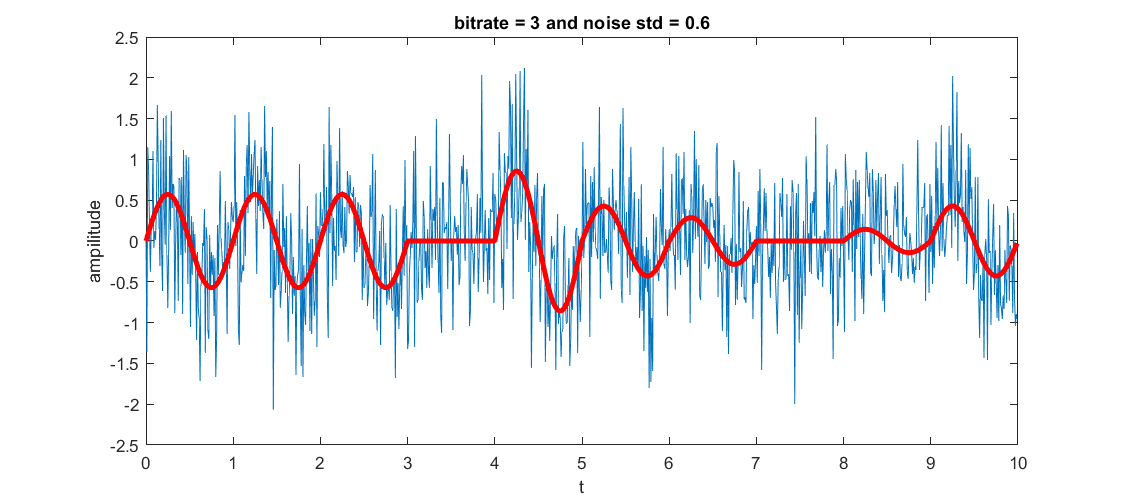

y = coding_amp(message, 3, mapset);
y_noisy = y + 0.6 * randn(size(y));
t = 0:ts:length(y)/100 - ts;
figure('Position', [0 0 900 400]);
plot(t, y_noisy);
hold on;
plot(t, y, 'Color', 'red', 'LineWidth', 3);
hold off;
xlabel('t');
ylabel('ampilitude');
title("bitrate = " + num2str(bit_rates(i)) + " and noise std = " + 0.6);

## 1.9 Make signal more persistant

to acheive this, we can increase amplitude of signals, so the range of each bit correlation increase and noises become less effective, as we increase range of a bit.

## 1.10

Theorically we can increase bit rate to infinity, but in reality computers have limits in calculating float numbers, so as we increase bit rate, the correlation boundaries become more and more smaller, and approaches to zero, so the computers can not handle them anymore because from a threshold they are similar to zero for computing.

## 1.11

It is obvious that it does not help, imagine we make amplitude of a signal by m times, so the recieved signal is like m × signal + noise, but if we multply it after receiving it wil be m × (signal + noise) = m × signal + m × noise, so we increase the noise as well. So it will not help us to reach our goal.

## 1.12

ADSLs are about 24 Mbps, it means they transfer 24 million bits per second, in this project we done decoding with only 3 bits per second!

# Part 2

clearvars;

In this section we want to calculate distance of a car by send and receive a signal and then proccess it.

                                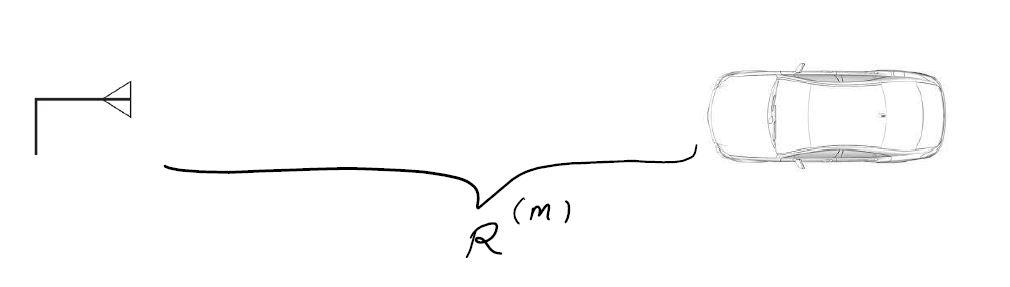

First we send a signal:

                                            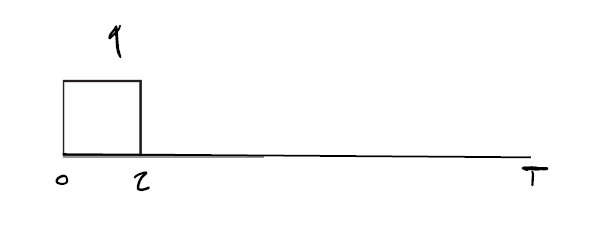

which is

- T = ${10}^{-5}$

- $f_s$ (sampling rate) = ${10}^{-9}$

- 
$$\tau ={10}^{-6}$$


## 2.1 

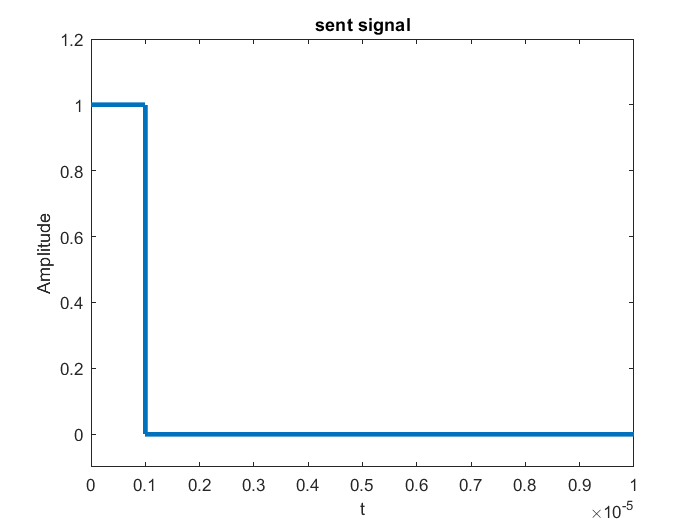

ts = 1e-9;
T = 1e-5;
tau = 1e-6;

t = 0:ts:T;
sent_signal = zeros(size(t));
sent_signal(1:int64(tau/ts)) = 1;
figure;
plot(t,sent_signal,'LineWidth',3);
axis([0 1e-5 -0.1 1.2]);
xlabel('t');
ylabel('Amplitude');
title('sent signal');

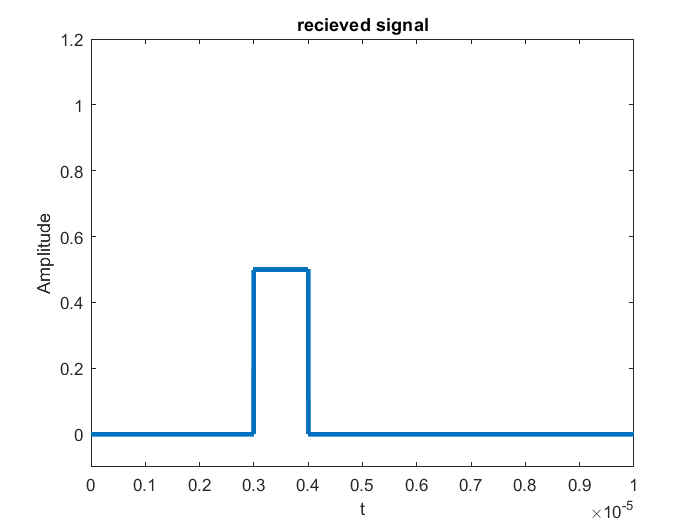

R = 450;
c = 3e8;
td = 2 * R / c;

received_signal = zeros(size(t));
alpha = 0.5;
received_signal(int64(td/ts):int64((td+tau)/ts)) = 0.5;
figure;
plot(t,received_signal,'LineWidth',3);
axis([0 1e-5 -0.1 1.2]);
xlabel('t');
ylabel('Amplitude');
title('recieved signal');

## 2.2 Estimating distance using convolution

To estimate the distance, we need to see where the most convolution happens, because two signals have most similarity there.

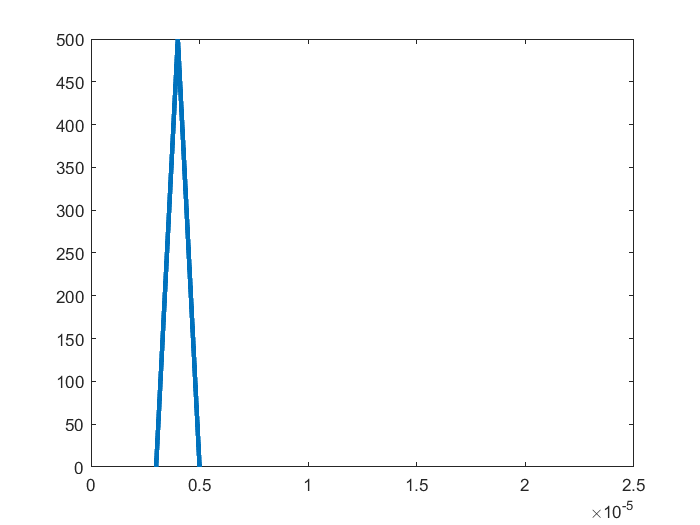

t_conv = 0:ts:2*T;
y_conv = conv(sent_signal, received_signal);
plot(t_conv, y_conv,'LineWidth',3);

[a, max_conv] = max(y_conv);
td_estimated = max_conv * ts - tau;   

estimated_distance = td_estimated * c / 2

estimated_distance = 449.8500

## 2.3 Effect of noise

As we can see in the following plots, increasing the noise will increase error amount(which is abseloute difference of actual distance and estimated one), up to std < 3.5, the error is less than 10, but it grows more as std gets bigger.

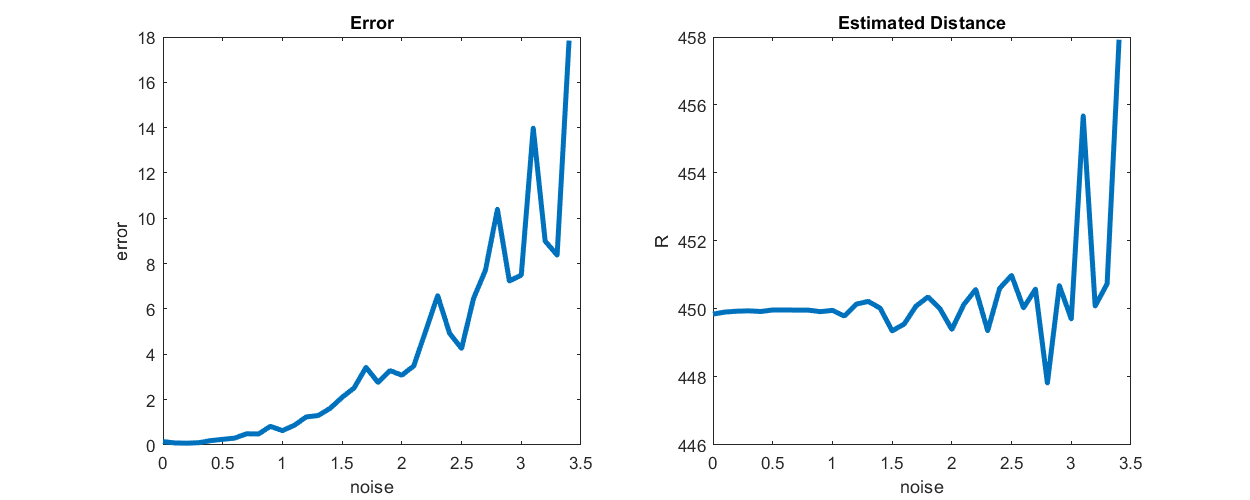

noise = 0;
k = 100;
R = 450;
noise_raise = 0.1;
errors = zeros(1,k);
t_conv = 0:ts:2*T;
Rs = zeros(1,k);
last_err = 0;
i = 1;
while(last_err < 15)
    sum_err = 0;
    sum_R = 0;
    for j=1:100
        y_conv = conv(sent_signal, received_signal + noise * randn(size(received_signal)));
        [a, max_conv] = max(y_conv);
        td_estimated = max_conv * ts - tau;
        estimated_R = td_estimated * c / 2;
        sum_err = sum_err + abs(R - estimated_R);
        sum_R = sum_R + estimated_R;
    end
    errors(i) = sum_err / 100;
    Rs(i) = sum_R / 100;
    last_err = errors(i);
    i = i + 1;
    noise = noise + noise_raise;
end

last = i - 1;
u = (0 : noise_raise : noise_raise * (last - 1));
figure('Position', [0 0 1000 400]);

subplot(1, 2, 1);
plot(u, errors(1:last), 'LineWidth', 3);
title('Error');
xlabel('noise');
ylabel('error');

subplot(1, 2, 2);
plot(u, Rs(1:last), 'LineWidth', 3);
title('Estimated Distance');
xlabel('noise');
ylabel('R');

# Part 3:

First we create a audio dataset, then by parsing numbers we can achevie our goal.

shomare = 17;
baje = 44;

[sound_data, sample_rate] = calling_customer(shomare, baje);
sound(sound_data, sample_rate);

# Part 4:

## 4.1 Training with all features using SVM

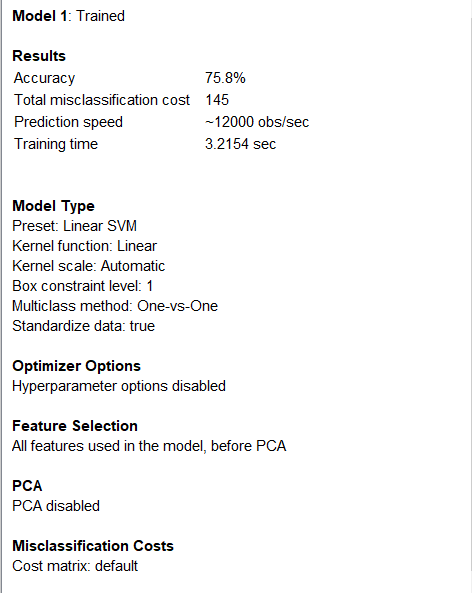

## 4.2 Training with only one feature at a time

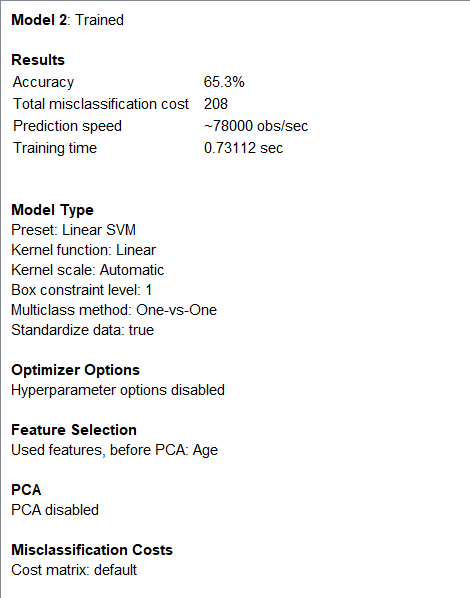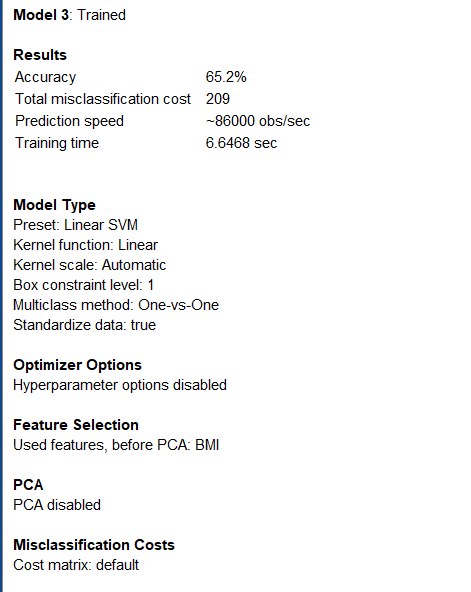

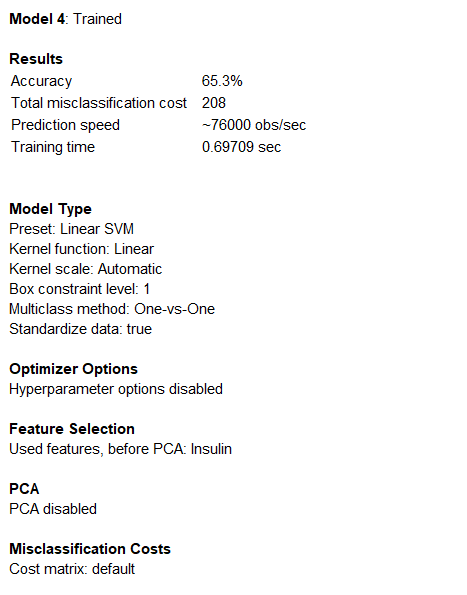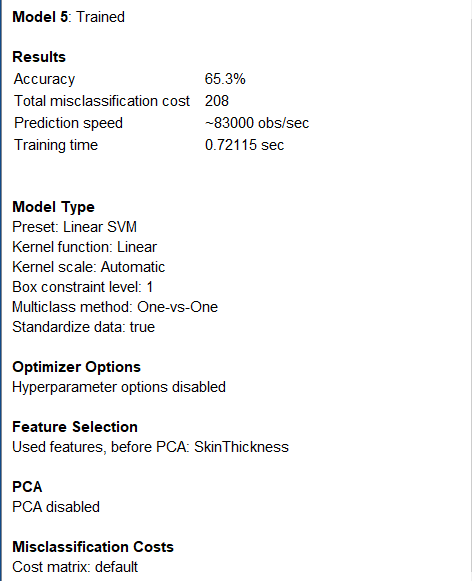

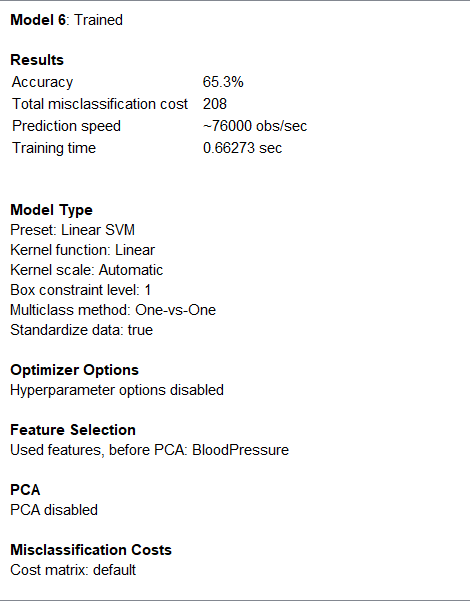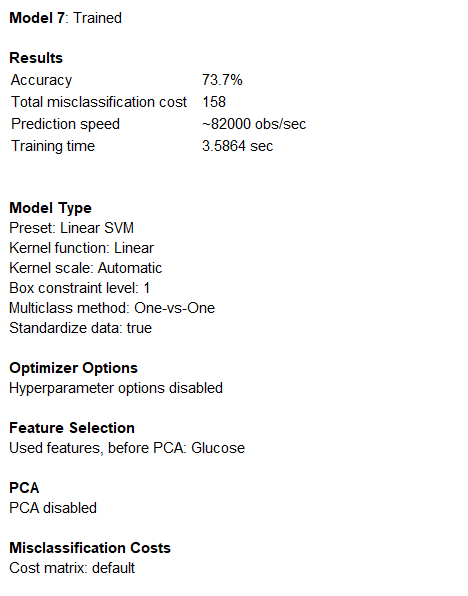

As we can see:

- All features: 75.8%

- Age: 65.3%

- BMI: 65.2%

- Insulin: 65.3%

- Skin thickness: 65.3%

- Blood Pressure: 65.3%

- Glocose: 73.7%

we can conclude that amount of glocose has most effect on having diabetes. 

## 4.3 Train Accuracy

train_data = readtable('diabetes-training.csv');
train_predicted = trainedModel.predictFcn(train_data);
train_acc = mean(table2array(train_data(:,'label')) == train_predicted);
fprintf("train accuracy: %.3f\n", train_acc);

train accuracy: 0.775


## 4.4 Test Accuracy


test_data = readtable('diabetes-validation.csv');
train_predicted = trainedModel.predictFcn(test_data);
test_acc = mean(table2array(test_data(:,'label')) == train_predicted);
fprintf("test accuracy: %.3f\n", test_acc);

test accuracy: 0.780


# Functions:

function [coded_string] = encode_string(message, mapset)
    coded_string = '';
    for i = 1:length(message)
        bit_string = mapset{2, strcmp(mapset(1,:), message(i))};
        coded_string = [coded_string, bit_string];
    end
end
function [mapset] = create_mapset()
    mapset = cell(2, 32);
    list = char('a':'z');
    list = [list ,' ', '.', ',','!', '"', ';'];

    for i = 1:32
        character = list(i);
        bit_string =  dec2bin(i - 1, 5);
        mapset{1, i} = character;
        mapset{2, i} = bit_string;
    end
end
function [coded_amp] = coding_amp(message, bit_rate, mapset)
    while(mod(length(message), bit_rate) ~= 0)
        message = [message, ';'];
    end
    
    Ts = 100;
    fs = 1 / Ts;
    t = 0:fs:1-fs;
    
    bit_string = encode_string(message, mapset);
    coded_amp = [];
    for i = (1:bit_rate:length(bit_string))
        ratio = bin2dec(bit_string(i:i+bit_rate-1));
        new_signal = ratio / (2 ^ bit_rate - 1) * sin(2 * pi * t);
        coded_amp = [coded_amp, new_signal];
    end
end
function [res] = custom_corr(arr1, arr2)
    res = 0.01 * dot(arr1, arr2);
    if(res < 0)
        res = 0;
    end
    if(res > 1)
        res = 1;
    end

end
function [message] = decoding_amp(coded_amp, bit_rate, mapset)
    Ts = 100;
    fs = 1 / Ts;
    t = 0:fs:1-fs;
    
    code_string = '';
    template_amp = 2 * sin(2 * pi * t);
    interval = 1 / (2 ^ bit_rate - 1);
    for i = (1:Ts:size(coded_amp,2))
        sliced_amp = coded_amp(i:i+Ts-1);
        sample_corr = custom_corr(sliced_amp, template_amp);
        for j = 0:(2 ^ bit_rate - 1)
            th_left = max(0, j * interval - interval / 2);
            th_right = min(1, j * interval + interval / 2);
            if(sample_corr >= th_left && sample_corr <= th_right)
                code_string = [code_string, dec2bin(j, bit_rate)];
                break;
            end
        end        
    end
    
    message = '';
    for i = 1:5:length(code_string)
        char = mapset{1, strcmp(mapset(2,:), code_string(i:i+4))};
        message = [message, char];
    end
end
function [callback_audio, sample_rate] = calling_customer(shomare, baje)
    callback_audio = [];
    directory = "./Audio/";
    
    number = shomare;
    [soundData, sample_rate] = audioread(directory + "number.ogg");
    callback_audio = [callback_audio; soundData];
    if(number <= 20 || mod(number, 10) == 0)
        [soundData, ~] = audioread(directory + num2str(number) + ".ogg");
        callback_audio = [callback_audio; soundData];
    else
        first = number - mod(number, 10);
        [soundData, ~] = audioread(directory + num2str(first) + ".ogg");
        callback_audio = [callback_audio; soundData];
        
        [soundData, ~] = audioread(directory + "and.ogg");
        callback_audio = [callback_audio; soundData];
        
        second = mod(number, 10);
        [soundData, ~] = audioread(directory + num2str(second) + ".ogg");
        callback_audio = [callback_audio; soundData];
    end
    
    [soundData, ~] = audioread(directory + "baje.ogg");
    callback_audio = [callback_audio; soundData];
    
    number = baje;
    if(number <= 20 || mod(number, 10) == 0)
        [soundData, ~] = audioread(directory + num2str(number) + ".ogg");
        callback_audio = [callback_audio; soundData];
    else
        first = number - mod(number, 10);
        [soundData, ~] = audioread(directory + num2str(first) + ".ogg");
        callback_audio = [callback_audio; soundData];
        
        [soundData, ~] = audioread(directory + "and.ogg");
        callback_audio = [callback_audio; soundData];
        
        second = mod(number, 10);
        [soundData, ~] = audioread(directory + num2str(second) + ".ogg");
        callback_audio = [callback_audio; soundData];
    end
end